## Stochasticity in the task dynamics model: parameters and equation

Usually, we choose fixed values for the model parmeters, e.g., we say stiffness k = 1.

Alternatively, we could introduce stochasticity in the form of Gaussian noise into the model by drawing the parameters from a *distribution*. In this case, we could for instance say stiffness has a distribution with mean 1 and standard deviation 0.01. Crucially, the amount of noise or stochasticity depends on the standard deviation of the distribution.

We try this out with three different amounts of noise:

- Pink is smaller amount of noise.

- Green is larger amount of noise.

The distributions look like this. This is where we draw our parameter value from in the following simulations, e.g., stiffness and damping.

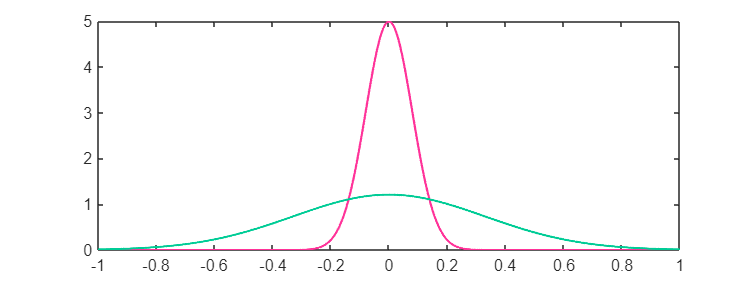

warning('off')

s1 = 0.00;
s2 = 0.08;
s3 = 0.33;

x = (-1:.001:1);

figure('Renderer', 'painters', 'Position', [10 10 800 300]);

pink = [255 51 153] / 255;
green = [0 204 150] / 255;

set(0, 'DefaultLineLineWidth', 1.33);

y = normpdf(x,0,s2);
plot(x,y,'Color',pink); hold on;
y = normpdf(x,0,s3);
plot(x,y,'Color',green); hold off;

In addition, we make the force function of the anharmonic oscillator itself noisy by adding noise in each step of the solution, see function below.

Now, we simulate the bababa trajectories:

- First, we apply no noise.

- Second, we only apply noise to the parameters, i.e., the parameter values are drawn from Gaussian distributions.

- Third, we apply noise to the parameters *and* the gesture itself.

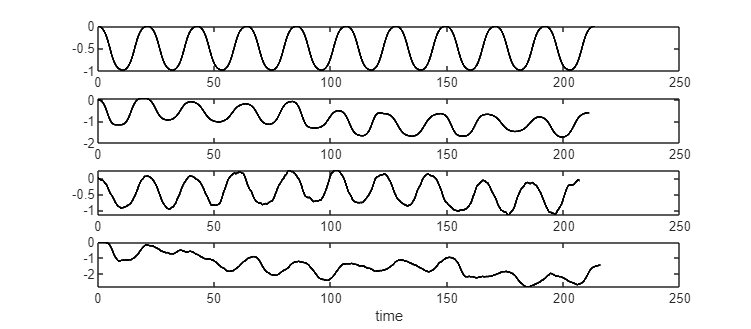

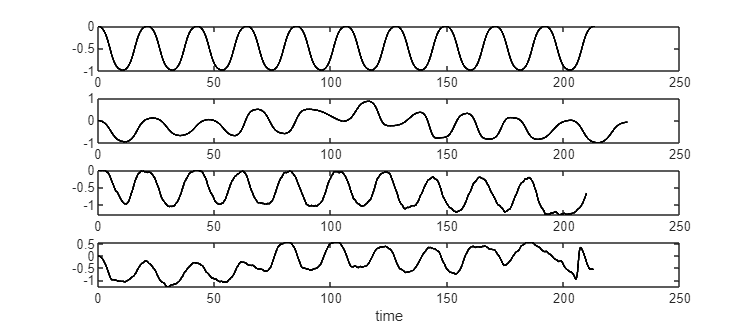

noise_params = 0.33;
noise_function = 80;

this_path = fileparts(matlab.desktop.editor.getActiveFilename);

num_simulation_runs = 2;

for sims = 1:num_simulation_runs
    h = figure('Renderer', 'painters', 'Position', [0 0 800 350]);

    start_simulation(m, 1, 0.0, 0.0, "black", this_path)
    start_simulation(m, 2, noise_params, 0.0, "black", this_path)
    start_simulation(m, 3, 0.0, noise_function, "black", this_path)
    start_simulation(m, 4, noise_params, noise_function, "black", this_path)

    fig_path = this_path + "/sim_figures/" + m + ".png";
    print('-r600', gcf, '-dpng', fig_path)

end

**Function to start simulation**

Arguments: 

- iter: number of maximal iterations

- subplot number: number of subplot on which result should be plotted

- sigma_p: standard deviation for Gaussian noise on parameters

- sigma_g: standard deviation for Gaussian noise on gestural equation

- col: color for plot

- file_path: where to store output

function start_simulation(iter, subplot_nr, sigma_p, sigma_g, col, file_path)
nplots = 4;
subplot(nplots, 1, subplot_nr);
rand_state = rng();
save(file_path + "/rand_states/" + iter + "_" + subplot_nr + ".mat", "rand_state");
simulate_baba_anh(sigma_p, sigma_g, col);
if (subplot_nr < 4)
    xlabel('');
end
end

**Anharmonic simulation**

Arguments: 

- sigma_p: standard deviation for Gaussian noise on parameters

- sigma_g: standard deviation for Gaussian noise on gestural equation

- col: color for plot

function X = simulate_baba_anh(sigma_p, sigma_g, col)

t = (0);
X = [0,-1];
for i = 1:20
    gest_end_time = t(end);

    % end state of last gesture
    xe = X(end,1);

    % stiffness
    k = 1 + sigma_p * randn;

    % damping
    b = 2*sqrt(k) + sigma_p * randn;

    % parameter for anharmonic potential (Sorensen & Gafos 2016)
    d = 0.95;

    % initial state
    % start tiny bit "inwards" away from the shoulder of the anharmonic
    % potential to avoid "falling over"
    xi = sqrt(k / d) * 0.97;

    % solve using Euler-Maryuma method
    X1 = NaN;
    while (isnan(X1))
        [t, X] = solve_euler(xi, k, b, d, sigma_g);
        X1 = X(end,1);
    end

    t = t + gest_end_time;

    % transform gesture to change direction
    % and start at end point of last syllabe
    if (mod(i,2) == 0)
        X(:,1) = -X(:,1);
    end
    X(:,1) = X(:,1) + (xe - X(1,1));

    plot(t, X(:,1), "Color", col); hold on;

end

hold off;
xlabel('time')

end

**Solution of the anharmonic oscilator using the Euler-Maryuma method**

Arguments:

- xi: initial state

- k: stiffness

- b: damping

- d: parameter for negative quartic term in anharmonic oscillator of Sorensen & Gafos 2016: V(x) = kx^2/2- dx^4/4

- s: standard deviation of the Gaussian noise

function [t,X] = solve_euler(xi, k, b, d, s)

% time step
dt = 0.001;

% maximal simulation iterations
N = 15000;

% initial states (time, position, velocity)
t(1) = 0;
x(1) = xi;
v(1) = 0;

% simulate until velocity threshold reached
i = 2;
done = 0;
while done == 0 && i <= N

    dx = v(i-1);

    dv = -b*v(i-1) - (k * x(i-1) - d * x(i-1)^3) + s * randn * sqrt(dt);

    x(i) = x(i-1) + dx * dt;
    v(i) = v(i-1) + dv * dt;
    t(i) = t(i-1) + dt;

    % Stop integration when velocity threshold is reached
    % Gestural activation needs to be included
    if (t(i) > 10 && abs(v(i)) < 0.01)
        done = 1;
    end

    i = i + 1;
end

X = [x(:), v(:)];

end